# Correlation of the Indicators

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Plot the correaltion matrix between the indicators, test the null hypothesis, find optitmum distributions of indicators for the octagon

clc
clear 
close all
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'DefaultTextInterpreter','latex');

## Load Data

load ../Data/Tab_Indicators.mat
load ../Data/Clean_Mirrors.mat

## Correlation

Tab_Indicators=rmmissing(Tab_Indicators);
M=Tab_Indicators(:,2:9);
M.Properties.VariableNames={'GDP';'HDI';'Energy';'Renewables';'Land';'Water';'MF';'CO2'};
[R,P] = corrcoef(table2array(M));

## Figure Correlations

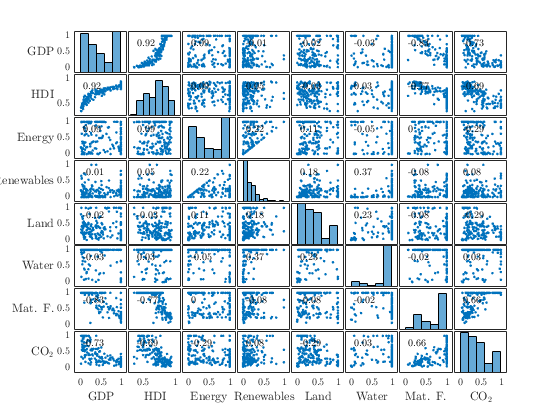

figure('WindowState', 'maximized')
[S,ax,BigAx,H,HAx]=plotmatrix(table2array(M));
set(gca,'Fontsize',12,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
    'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
[r,c]=size(R);
k=1;
for j=1:c
    for i=1:r
    if(i~=j)
        S(k).DisplayName=num2str(R(i,j));
        h_x=legend(S(k),'Color','none','Location','northwest','box','off');
        annotation('textbox',get(h_x,'Position'),'String',num2str(round(R(i,j),2)),...
            'EdgeColor','none','FontSize',10,'FontWeight','bold','interpreter','latex');
        set(h_x,'visible','off')
    end
    k=k+1;
    end
end
hF=gcf;
hA=hF.Children;
% Labels
Label={'GDP';'HDI';'Energy';'Renewables';'Land';'Water';'Mat. F.';'$\mathrm{CO_2}$'};
for n=1:length(Label)
    ylabel(ax(n,1),Label(n),'Rotation',0,'FontSize',12,'HorizontalAlignment','right','VerticalAlignment','middle')
    xlabel(ax(end,n),Label(n),'Rotation',0,'FontSize',12,'HorizontalAlignment','center')
end

% print(gcf,'-dpdf','-bestfit','Correlation_Indicator.pdf')

## Null Hypothesis

From the Mathworks website:

The diagonal entries are all ones and the off-diagonal entries are the p-values for each variable pair. P-values range from 0 to 1, where values close to 0 correspond to a significant correlation in R and a low probability of observing the null hypothesis.

 "... a matrix of p-values for testing the hypothesis of no correlation.  Each p-value is the probability of getting a correlation as large as the observed value by random chance, when the true correlation is zero."

Lab={'GDP';'HDI';'Energy';'Renewables';'Land';...
    'Water';'MF';'CO2'};
Tab_Null=[Lab,array2table(P)];
Tab_Null.Properties.VariableNames={'Var';'GDP';'HDI';'Energy';'Renewables';'Land';...
    'Water';'MF';'CO2'}

Tab_Null = 8×9 table
         Var             GDP           HDI         Energy      Renewables       Land         Water           MF           CO2    
    ______________    __________    __________    _________    __________    __________    __________    __________    __________

    {'GDP'       }             1    1.1738e-67      0.23606       0.90412       0.76074       0.70357    8.9598e-44    1.8433e-28
    {'HDI'       }    1.1738e-67             1       0.2258       0.49202       0.73589       0.73133    1.3659e-33    7.1676e-25
    {'Energy'    }       0.23606        0.2258            1     0.0040154       0.16643       0.51703       0.96081     0.0002067
    {'Renewables'}    

## Optimum

Description: Compare all the permutations, find the optimum distribution that has higher correlation between indicators

N=2:8;
Perm=perms(N);
% Eliminate mirrors
Perm(find(isnan(L)),:)=[];
% Add vector 1 at begining and end
Perm= [ repmat(1,size(Perm,1),1) Perm  repmat(1,size(Perm,1),1)];

for n=1:size(Perm,1)
    V=Perm(n,:);
    for m=2:size(Perm,2)
        i=V(m-1);
        j=V(m);
        Coef(n,m-1)=abs(R(i,j));
    end
    Coef(n,m)=sum(Coef(n,:));
end

Tab_Cor=array2table(Coef)

Tab_Cor = 2520×9 table
     Coef1      Coef2      Coef3       Coef4       Coef5       Coef6       Coef7        Coef8      Coef9 
    _______    _______    ________    ________    ________    ________    ________    _________    ______

    0.72748    0.65596    0.020011      0.2255     0.17836     0.22284    0.094804       0.9187    3.0437
    0.72748    0.65596    0.020011      0.2255     0.17836    0.053861    0.094804     0.092749    2.0487
    0.72748    0.65596    0.020011      0.2255     0.10823     0.22284    0.053861       0.9187    2.9326
    0.72748    0.65596    0.020011      0.2255     0.10823    0.094804    0.053861    0.0094492    1.8953
    0.72748    0.65596    0.020011


% Coef 9 is the sum
%Max=find(Coef(:,9)==max(Coef(:,9)));
 Max=find(Coef(:,9)>=3.6,1)

Max = 561

I_M=Perm(Max,:)

I_M =      1     8     3     4     6     5     7     2     1



% Original distribution of the indicators
LI={'GDP','HDI','Energy','Renewables','Land','Water','Mat. F.','CO2'};

% Distribution of the indicators based on the correlation
LI(I_M) 

ans = 1×9 cell array
    {'GDP'}    {'CO2'}    {'Energy'}    {'Renewables'}    {'Water'}    {'Land'}    {'Mat. F.'}    {'HDI'}    {'GDP'}
